**Open the WorkDataSets WorkSpace (contains three different tables of the phased curves from the old and the current dataset at T0 and from the samples of the anisotropy experiment).**

%Table Editor
var = {'string','cell','cell'};
varnames = {'Sample' 'Time' 'Data'};
ShelfLifeTable = table('Size',[54,3],'VariableTypes',var,'VariableNames',varnames);
ShelfLifeTable(:,"Sample") = ShelfLifeSet(1,:)';
Time = cell(54,1);
for k = 1:length(Time)
Time{k} = ShelfLifeSet{2,k}.time;
end
ShelfLifeTable(:,"Time") = Time;
Data = cell(54,1);
for k = 1:length(Data)
    Data{k} = ShelfLifeSet{2,k}.data;
end
ShelfLifeTable(:,"Data") = Data;

FrozenCurdPercent = zeros(54,1);
for k = 1:length(FrozenCurdPercent)
    if contains(ShelfLifeTable.Sample(k),"_0F_") == 1
        FrozenCurdPercent(k,1) = 0;
    elseif contains(ShelfLifeTable.Sample(k),"_16_") == 1
         FrozenCurdPercent(k,1) = 16;
    else 
        FrozenCurdPercent(k,1) = 100;
    end
end
ShelfLifeTable = [ShelfLifeTable array2table(FrozenCurdPercent)];

%vector to be used later to determine test order (necessary for both
%training and validation sets)
contvars = TCTable.FrozenCurdPercent;

%creating the training and validation set (4 shelf life set only)
pattern2 = ["MozzT2_0F_1_1" "MozzT3_0F_2_1" "MozzT4_0F_3_2" "MozzT2_16_2_2" "MozzT3_16_1_2" "MozzT4_16_3_1" "MozzT2_100_2_1" "MozzT3_100_1_1" "MozzT4_100_3_2"];
idx2 = contains(ShelfLifeTable.Sample,pattern2);
ShelfLifeValid = ShelfLifeTable(idx2,:);
ShelfLifeTable(idx2,:) = [];
ShelfLifeTrain = ShelfLifeTable;

%RIMOZIONE DEGLI OUTLIERS
pattern = ["TC1_DX_2_" "TC3_DX_2_"];
idx = contains(TCTable.Sample,pattern);
TCTable(idx,:) = [];
%categories(idx,:) = [];
contvars(idx,:) = [];

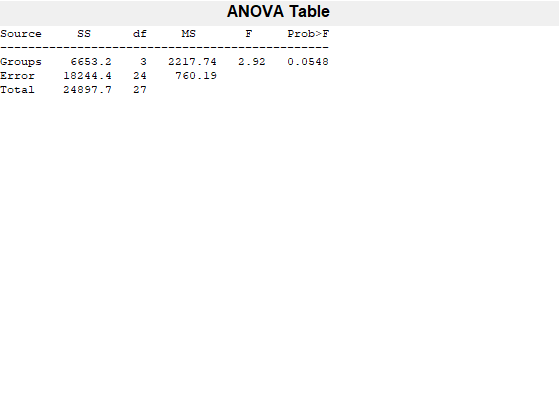

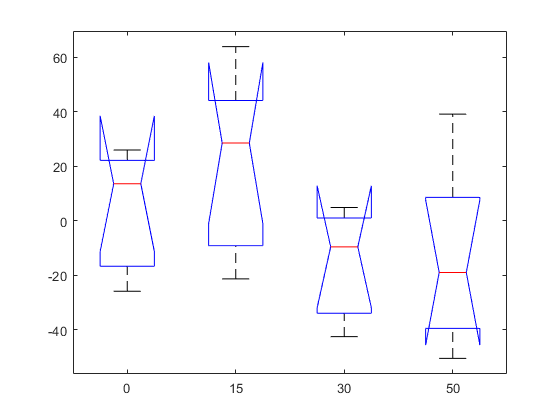

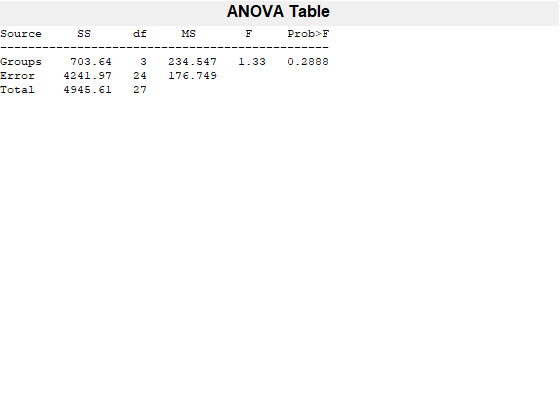

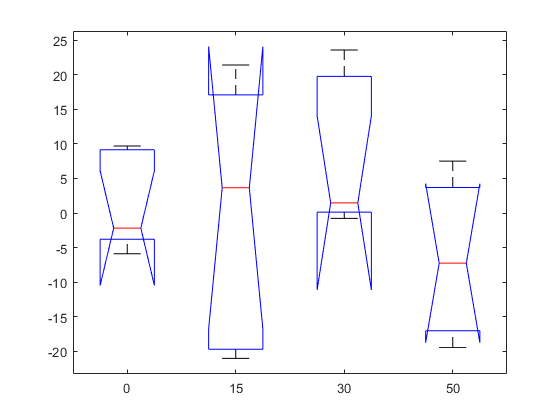

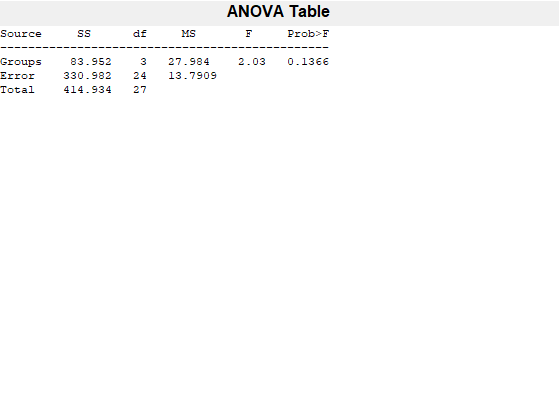

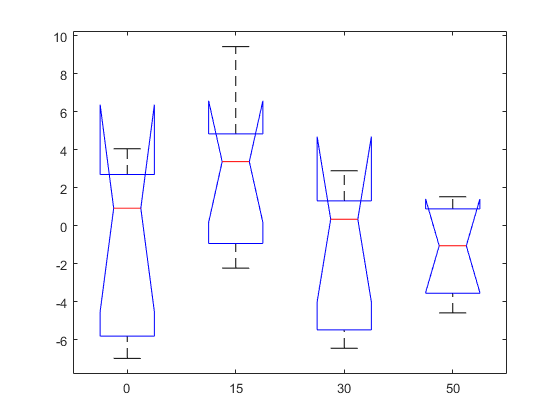

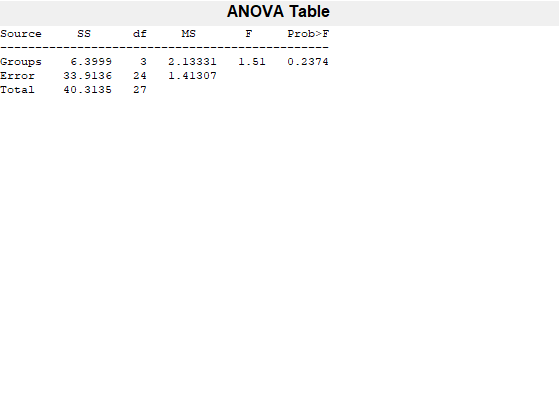

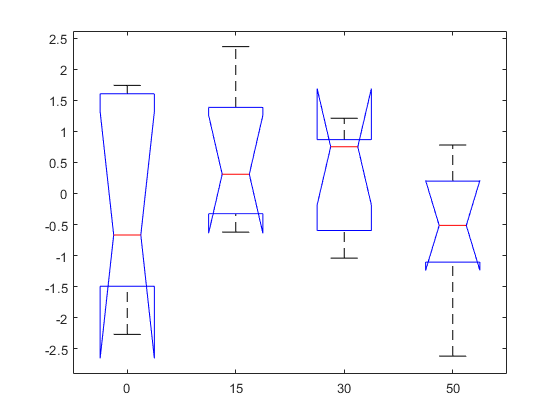

% Principal Components Analysis of the dataset used for pls training
curves = zeros(1129,height(TCTable));
for k = 1:height(TCTable)
    curves(:,k) = TCTable.Data{k}; 
end
curves = curves';
curves = normalize(curves);
[n,m] = size(curves);


[coeff,score,~,~,explained] = pca(curves);

%PC ranking based on discriminant power
pvalues = zeros(length(score)-1,1);
for k = 1:length(score)-1
    [p,~,~] = anova1(score(:,k)',TCTable{:,"FrozenCurdPercent"}');
    pvalues(k,1) = p;
end


pvalues = array2table(pvalues);
PCorder = cell(length(score)-1,1);
form = 'PC%d';
for k = 1:length(score)-1
    PCorder{k} = sprintf(form,k);
end
PCorder = cell2table(PCorder);
PCorder = [PCorder pvalues];
PCorder = sortrows(PCorder,'pvalues','ascend'); %sorted table of PC's p-values 

pcorderidx = zeros(height(PCorder),1); %row index to sort scores matrix in descending discrimination power
for k = 1:height(PCorder)
    pcorderidx(k,1) = sscanf(PCorder.PCorder{k},strcat("PC","%d"));
end

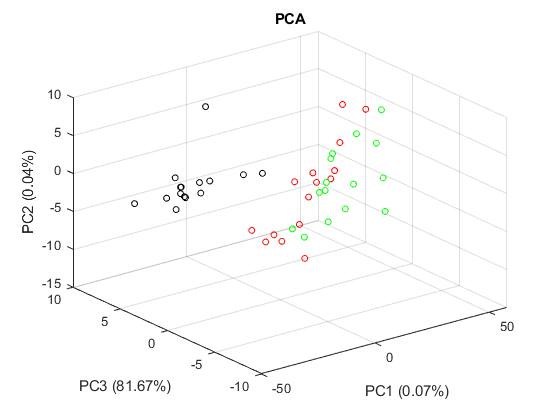

%PCA scores plot
colourmap = zeros(height(ShelfLifeTrain),3); %colourmap
for k = 1:length(colourmap)
    if contains(ShelfLifeTrain.Sample(k),"_0F_") == 1
        colourmap(k,:) = [1 0 0]; %red
    elseif contains(ShelfLifeTrain.Sample(k),"_16_") == 1
          colourmap(k,:) = [0 1 0]; %green
   % elseif ismember(TCTable.categories(k),"TC3") == 1
    %      colourmap(k,:) = [0 0 1]; %blue
    else 
          colourmap(k,:) = [0 0 0]; %black
    end
end

scatter3(score(:,1),score(:,3),score(:,2),20,colourmap)
title("PCA");
xlabel("PC1 (0.07%)");
ylabel("PC3 (81.67%)");
zlabel("PC2 (0.04%)");

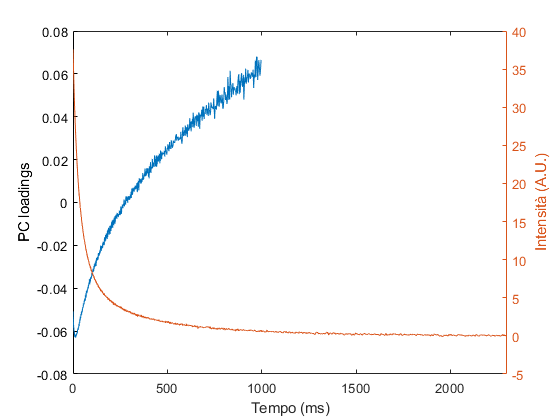

%plot of the PC loadings vs. the relaxation time, good to look at it
%anytime the dataset used in the PCA is modified
cla reset
plot(time,coeff(:,2),'-');
xlabel('Tempo (ms)');
ylabel('PC loadings');
%legend("PC1","PC3","PC4","PC2","PC5","location","bestoutside");

yyaxis right
plot(ShelfLifeTrain.Time{1},ShelfLifeTrain.Data{1},'-');
ylabel('Intensità (A.U.)');
xlim([0 2300]);

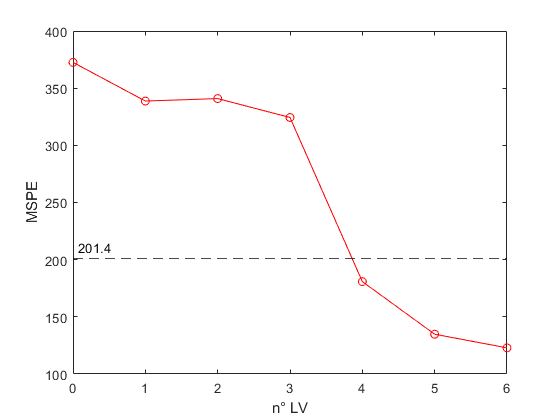

%PLS regression model training
score2 = score(:, pcorderidx); %score matrix sorted by descending disciminant power of pc
cvpart = cvpartition(TCTable.FrozenCurdPercent, 'LeaveOut');

ncomp = 6;
[XL,YL,XS,YS,BETA,PCTVAR,MSPE,stats] = plsregress(score2(:,1:8),TCTable.FrozenCurdPercent,ncomp,"cv",cvpart);

%MSEP plot vs. n° of LV to have a look on optimal LV number
cla reset
plot(0:ncomp,MSPE(2,:),'-or');
xlabel('n° LV');
ylabel('MSPE');
yline(201.4,'--k', '201.4','LabelHorizontalAlignment','Left');

%crossvalidation with leave one out partition
predictedY = zeros(height(TCTable),1);
predictionlogicarray = zeros(height(TCTable),1);
mspetrain = zeros(44,1);
for k = 1:length(predictedY)
    idxTrain = training(cvpart,k);
    idxTest = test(cvpart,k);
    dataTest = score2(idxTest,1:8);
    [~,~,~,~,betatrain,~,mspe,~] = plsregress(score2(idxTrain,1:8),TCTable.FrozenCurdPercent(idxTrain,:),ncomp);
    predictedY(k,:) = [ones(size(dataTest,1),1) dataTest]*betatrain;
    mspetrain(k,1) = mspe(2,7);
end

testorder = zeros(height(TCTable),1); %order of test samples which are predicted so it's possible to know 
                         %the actual and the predicted value for that test set
for k=1:length(testorder)
    testorder(k) = contvars(test(cvpart,k));
end

mean(mspetrain)

ans = 140.7564

std(mspetrain)

ans = 6.3933

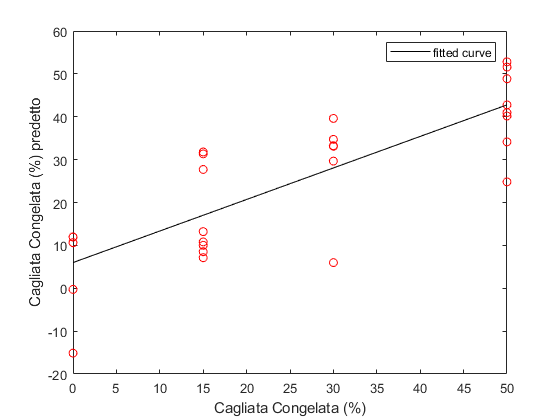

%correlation between actual and predicted values
[linearegress,gof] = fit(testorder,predictedY,'poly1');
[quadraticregress,gof2] = fit(testorder,predictedY,'poly2');

%plot of the correlation between actual and predicted value
cla reset
plot(testorder,predictedY,'ro')
hold on
plot(linearegress,'-k')
%plot(quadraticregress,'--k')
xlabel('Cagliata Congelata (%)');
ylabel('Cagliata Congelata (%) predetto');
%legend({'data','regression','quadratic regression'},"Location","northwest");
hold off 

Rsquaredlinear = gof.rsquare

Rsquaredlinear = 0.6561

Rsquaredquadratic = gof2.rsquare

Rsquaredquadratic = 0.6590

%Prediction of the validation set
curvesValidationSet = zeros(1129,height(ValidationTable)); %extraction of the curves from the validation set
for k = 1:height(ValidationTable)
    curvesValidationSet(:,k) = ValidationTable.Data{k}; 
end
curvesValidationSet = normalize(curvesValidationSet);
scoresValidationSet = curvesValidationSet'*coeff; %calculation of the scores from the PCA model multiplying
                                                   %the curves with PC loadings
predictedValidation = [ones(height(ValidationTable),1) scoresValidationSet(:,[5 1 9 3 22 8 4 2])]*BETA;
%MUST INSERT THE PC USED IN THE PLS MODEL AND WITH THE SAME ORDER
%calculation of the predicted quantity of frozen curd multiplying the scores obtained in the previous line with
%the pls coefficents
PLSscoresValiSet = scoresValidationSet(:,1:8)*stats.W;

%Prediction of the validation set
curvesValidationSet2 = zeros(1129,height(OldTable)); %extraction of the curves from the validation set
for k = 1:height(OldTable)
    curvesValidationSet2(:,k) = OldTable.Data{k}; 
end
curvesValidationSet2 = normalize(curvesValidationSet2);
scoresValidationSet2 = curvesValidationSet2'*coeff; %calculation of the scores from the PCA model multiplying
                                                   %the curves with PC loadings
predictedValidation2 = [ones(height(OldTable),1) scoresValidationSet2(:,[5 1 9 3 22 8 4 2])]*BETA;
%MUST INSERT THE PC USED IN THE PLS MODEL AND WITH THE SAME ORDER
%calculation of the predicted quantity of frozen curd multiplying the scores obtained in the previous line with
%the pls coefficents
PLSscoresValiSet2 = scoresValidationSet2(:,1:8)*stats.W;

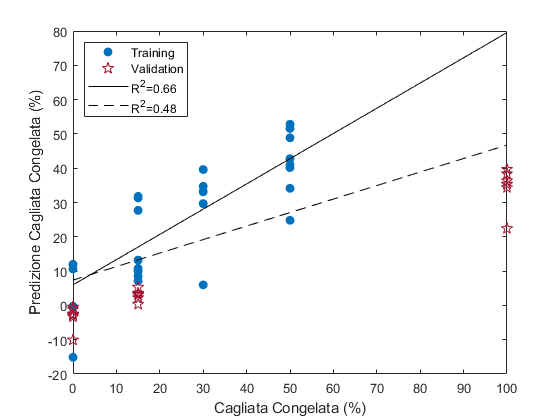

lineregrxaxis = [testorder; zeros(6,1); OldTable.FrozenCurdPercent(7:18,1)];
allpredictions = [predictedY; predictedValidation(1:6,:); predictedValidation2(7:18,1)];
y = [predictedValidation(1:6,:); predictedValidation2(7:18,1)];
x = [zeros(6,1); OldTable.FrozenCurdPercent(7:18,1)];
[Valilinearegress,Vgof] = fit(lineregrxaxis,allpredictions,'poly1');

cla reset
plot(testorder,predictedY,'o','MarkerFaceColor',[0 0.4470 0.7410])
hold on
plot(x,y,'p', 'MarkerSize',9,'MarkerEdgeColor',[0.6350 0.0780 0.1840]);
plot(linearegress,'-k');
plot(Valilinearegress,'--k');
hold off
legend({'Training','Validation','R^{2}=0.66','R^{2}=0.48'},'Location','northwest');
xlabel("Cagliata Congelata (%)");
ylabel("Predizione Cagliata Congelata (%)");

Vgof.rsquare

ans = 0.4797

%Hotelling's T squared test for PLS scores for one sample
mu = mean(XS(1:6,:));
m = mean(PLSscoresValiSet(1:15,:));
S = cov(PLSscoresValiSet(1:15,:));
t2 = 15*(m-mu)*inv(S)*(m-mu)'; %problem seems to come from here inv(S)
F = (15-6)/((15-1)*6)*t2;
v1 = 6;
v2 = 15-6;
P = 1 - fcdf(F,v1,v2); %working? no

for k = 1:10
    figure()
    plot(score2(:,k),contvars,'o')
    xlabel(sprintf("PC%d",k));
end

PC5 = score2(:,1)+3;

[mdl,~,statistics] = glmfit(PC5,contvars,"poisson","link","log");
[yhat,dylo,dyhi] = glmval(mdl,PC5,"log",statistics);
mdl2 = fitglm(PC5,contvars,"Link","log","Distribution","poisson");
